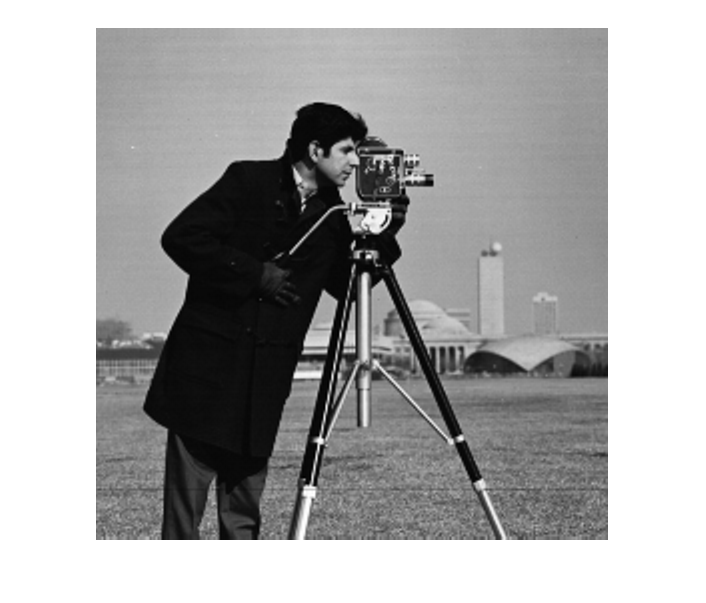

rng(0); % seed rng
cam = imread("./cameraman.png");
imshow(cam)

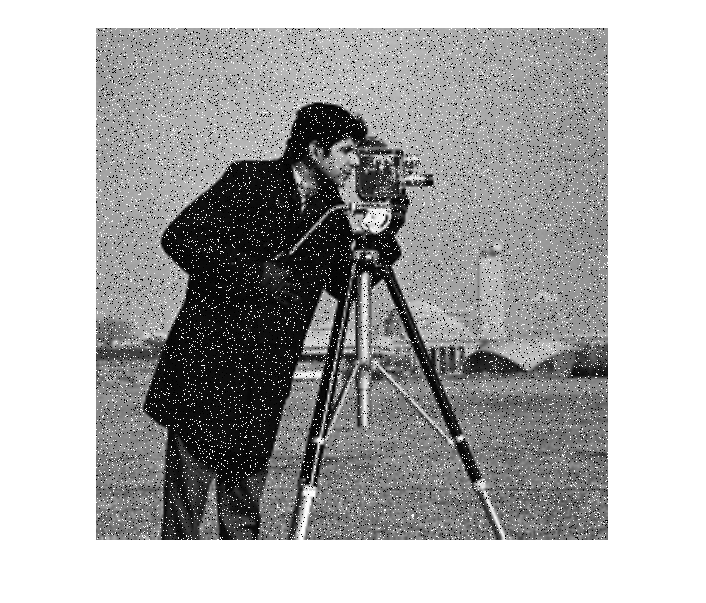

cam_noisy = imnoise(cam, ["salt & pepper"], 0.1);
imshow(cam_noisy)

%for i = 1:size(cam,1)
%    for j = 1:size(cam,1)
%        if mod(i, 10) == 0
%            cam_noisy(i, j) = randi([0, 255], [1,1], "uint8");
%        end
%    end
%end
%imshow(cam_noisy)
%cam_n = cam + 0.5 * randi([0, 255], size(cam), "uint8");
%imshow(cam_n)

L1 = [5, 2, 7, -8, 9]

L1 =      5     2     7    -8     9


my_median(L1)

ans = 5

L2 = [5, 2, 7, -8, 9, 50]

L2 =      5     2     7    -8     9    50


my_median(L2)

ans = 6

L3 = [5, 2, 7, -8, 1e6]

L3 =            5           2           7          -8     1000000


my_median(L3)

ans = 5

my_median([1])

ans = 1

%my_median([]);

block = cam_noisy(1:3, 1:3)

block = 3×3 uint8 matrix
   156   157   160
   156   157     0
   158   157   156


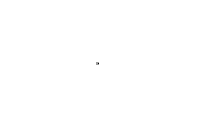

imshow(block)

block_list = block(:);
med = my_median(block_list)

med = uint8
157

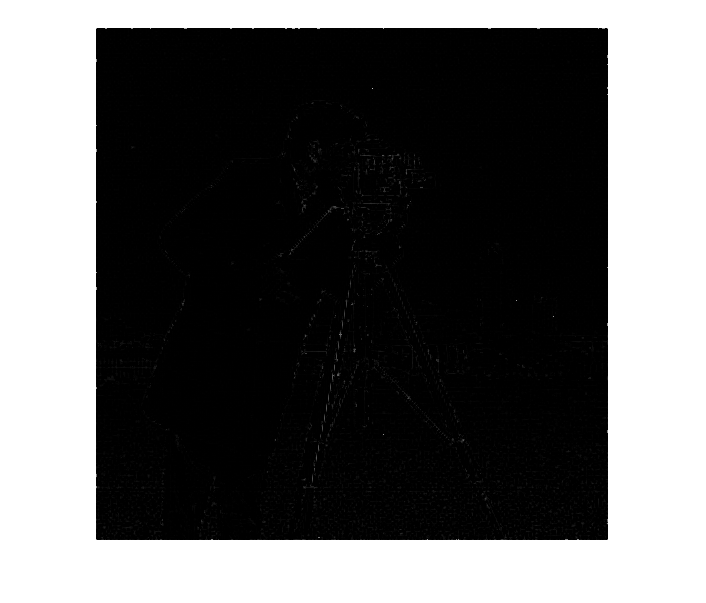

block(2,2) = med; % repeat for all blocks

repaired = medfilt2(cam_noisy);
imshow(cam - repaired)

function med = median(list)
    length = numel(list);
    if length == 1
        med = 0;
        return
    end
    list_sorted = sort(list);
    middle = ceil(length/2);
    if mod(length, 2) == 1 % odd
        med = list_sorted(middle);
    else % even
        med = (list_sorted(middle) + list_sorted(middle + 1)) / 2;
    end
end